addpath('../../Downloads/NIFTI_20110921/')
addpath('../skeletons/')
A = eye(3) + .1 * rand(3);
b = zeros(3,1) + .1 * rand(3,1);
[fixed,spacing] = myReadNifti('../images/atlas_2mm_1000_3.nii');
moving = myReadNifti('../images/atlas_2mm_1036_3.nii');
%apply smoothing
fixed = myGaussianLPF(fixed,3);
moving = myGaussianLPF(moving,3);
eta = .001

eta = 1.0000e-03

myAffineObjectiveDerivativeTest(A,b,fixed,moving,eta);

dE/dA(1,1) : Anl.D. =  3.348e+11  Num.D. =  3.347e+11  Err =     0.0003
dE/dA(1,2) : Anl.D. =  3.085e+11  Num.D. =  3.087e+11  Err =     0.0008
dE/dA(1,3) : Anl.D. =  3.738e+11  Num.D. =  3.739e+11  Err =     0.0005
dE/dA(2,1) : Anl.D. =  3.757e+10  Num.D. =  3.832e+10  Err =     0.0201
dE/dA(2,2) : Anl.D. =   1.57e+11  Num.D. =  1.591e+11  Err =     0.0129
dE/dA(2,3) : Anl.D. =   8.07e+10  Num.D. =  8.165e+10  Err =     0.0117
dE/dA(3,1) : Anl.D. =   1.79e+11  Num.D. =  1.776e+11  Err =     0.0076
dE/dA(3,2) : Anl.D. =  2.325e+11  Num.D. =  2.302e+11  Err =     0.0099
dE/dA(3,3) : Anl.D. =  3.427e+11  Num.D. =  3.396e+11  Err =     0.0091
dE/db(1)   : Anl.D. =  6.376e+09  Num.D. =  6.381e+09  Err =     0.0007
dE/db(2)   : Anl.D. =  1.326e+09  Num.D. =  1.315e+09  Err =     0.0086
dE/db(3)   : Anl.D. =  4.357e+09  Num.D. =  4.321e+09  Err =     0.0083


A_init = A;
b_init = b;
x_init =[A_init(:); b_init(:)];
opt=optimoptions('fminunc','Display','iter','GradObj','on','MaxIter',20);
f_opt = @(x)(myAffineObjective3DWrapper(x, fixed, moving));
[x_opt,E_opt] = fminunc(f_opt, x_init, opt);

                                                        First-order 
 Iteration  Func-count       f(x)        Step-size       optimality
     0           1      1.43832e+11                      3.74e+11
     1           4      6.80347e+10    1.42595e-13       3.22e+11  
     2           6      4.71648e+10       0.114728       2.08e+11  
     3           8      3.80422e+10       0.584221       1.25e+11  
     4           9      3.12484e+10              1       1.56e+11  
     5          11      2.82993e+10       0.423266       4.78e+10  
     6          12      2.80436e+10              1       2.84e+10  
     7          13      2.78567e+10              1        2.4e+10  
     8          14      2.76759e+10              1       1.17e+10  
     9          15      2.75981e+10              1       1.06e+10  
    10          16      2.75125e+10              1       9.46e+09  
    11          17      2.74006e+10              1       1.17e+10  
    12          18      2.73064e+10              

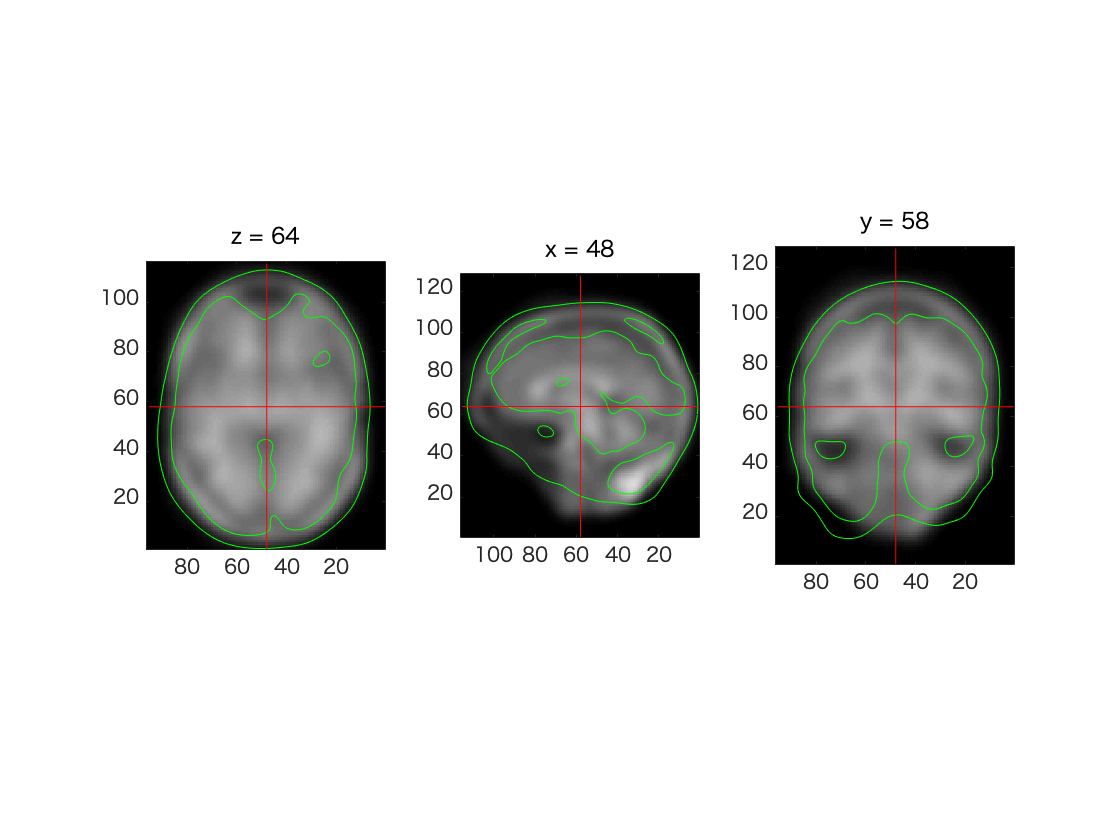

A_opt = reshape(x_opt(1:9),3,3); 
b_opt = x_opt (10:12);
myViewAffineReg(fixed,moving,A_opt,b_opt,spacing);

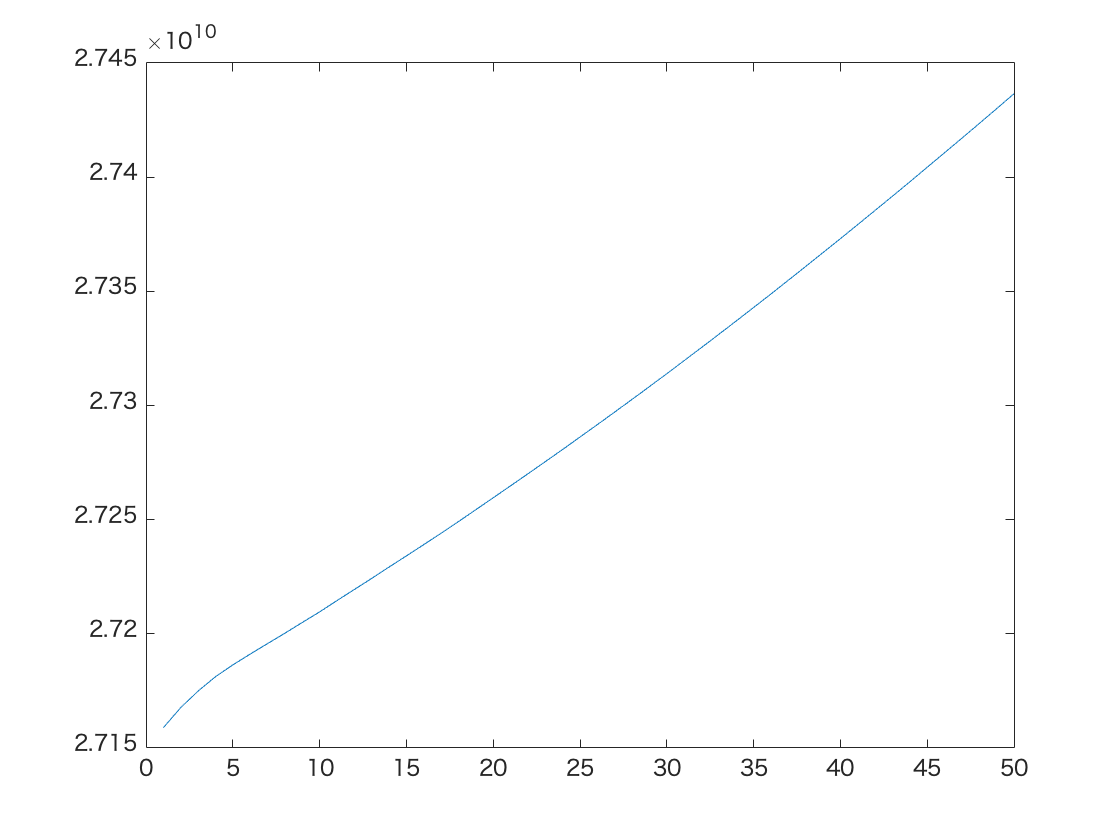

label_table = readtable('../images/labels.csv','Format','%u%s%s');
L = table2array(label_table(:,1));
ux = zeros(size(fixed));
uy = zeros(size(fixed));
uz = zeros(size(fixed));
E_plot = zeros(1,50);
moving = myTransformImage(fixed,moving,A_opt,b_opt,'linear');
for num = 1:50
    [E,ux,uy,uz] = myGreedyRegUpdate(ux,uy,uz,fixed,moving,sqrt(3),sqrt(.5),.5);
    E_plot(num) = E;
end
figure;
plot(E_plot);